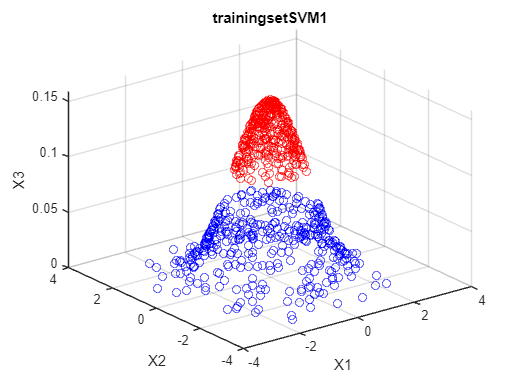

% 3.1

clc
clear

dataset = load('trainingsetSVM1.mat');

X = dataset.X;
Y = dataset.Y;

plot_dataset(X, Y, "trainingsetSVM1")

El conjunto de datos es separable linealmente. Un plano perpendicular a X3 sería capaz de separar las dos clases.

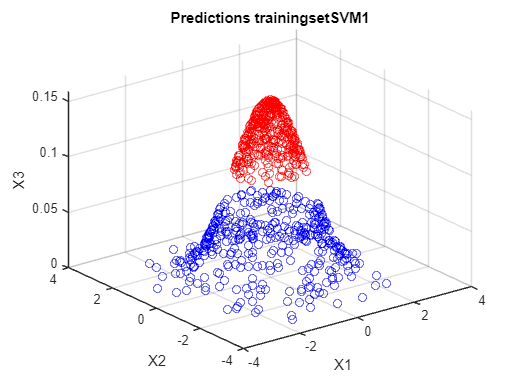

% 3.2

mdl = fitcsvm(X, Y, 'KernelFunction','linear', 'Standardize', true);
ye = predict(mdl,X);

plot_dataset(X, ye, "Predictions trainingsetSVM1");

function plot_dataset(X, Y, plot_title)
    % Matrix containing the colors of every sample
    colors = zeros(size(Y, 1), 3);
    
    % If for sample n, Y(n) is -1, colors(n) will be [0, 0, 1]. Color blue
    % If for sample n, Y(n) is 1, colors(n) will be [1, 0, 0]. Color blue
    colors_class1 = repmat([0, 0, 1], sum(Y == -1), 1);
    colors_class2 = repmat([1, 0, 0], sum(Y == 1), 1);
    
    % Change original color value [0,0,0] to the new calculated value. R or B.
    colors(Y == -1, :) = colors_class1;
    colors(Y == 1, :) = colors_class2;
    
    % Plot the dataset with the new colors.
    scatter3(X(:,1), X(:,2), X(:,3), [], colors)
    xlabel('X1');
    ylabel('X2');
    zlabel('X3');
    title(plot_title);
end
